# SC42025 Filtering & Identification

**MATLAB EXERCISE HW4**

**Instructions: Fill in the live script with your code and answers. Then export the live script as a pdf (in the 'Live Editor tab', click on the arrow under 'Save' and then 'Export to pdf').**

**General Hints:**

- The live script is devided in several sections. You can **execute the sections seperately.**

- To reduce the runtime, you can comment the test-functions. Make sure, that all test-functions are uncommented when you export the live script and that their output appears on the pdf. **Missing test-function output will be treated as "wrong" regardless of the implementation.**

- Please **do not change given variable names or variables or any other code that you are asked to not change**. Otherwise the functionality of the live script and the testfunctions cannot be guaranteed.

- If you decide to implement your functions in seperate files, make sure to copy the code to the bottom of the script before you export it.** Missing code will be treated as "wrong" regardless of the result of the testfunction. **

- Please read the** cheat sheet **carefully**.**

- Make sure to** upload a *.pdf file. Files in other formats will not be corrected.**

## Introduction

This exercise is split into two sections: 

In section 1, you are guided step-by-step through one iteration of the identification cycle with the PO-MOESP algorithm. In this section, the focus is on the correct implementation of the functions. We provide a toy data set and fix all parameters. You are asked to test your implementation with the provided test functions.

In section 2., you are asked to iteratively perform the identification cycle on the [Cascaded Tanks with Overflow](https://www.nonlinearbenchmark.org/benchmarks/cascaded-tanks) benchmark. For further information, please see M. Schoukens, P. Mattsson, T. Wigren and J.P. Noël, Cascaded tanks benchmark combining soft and hard nonlinearities, 4TU.ResearchData, Dataset, doi: 10.4121/12960104.

## Questions

## 1. Implementation

In this section, we implement all functions that are required to iteratively perform the complete identification cycle in section 2. 

At first, we implement the PO-MOESP algorithm. Then we implement the simulation of the system and implement two functions, which compute the VAF and RMSE, to assess the quality of the model. In the end, we perfom the validation step.

For this section, we work with the following data set of an output error system. The first 2/3 of the input-output data is used for training, the last 1/3 of the input-output data is used for validation.The data set is plotted below.

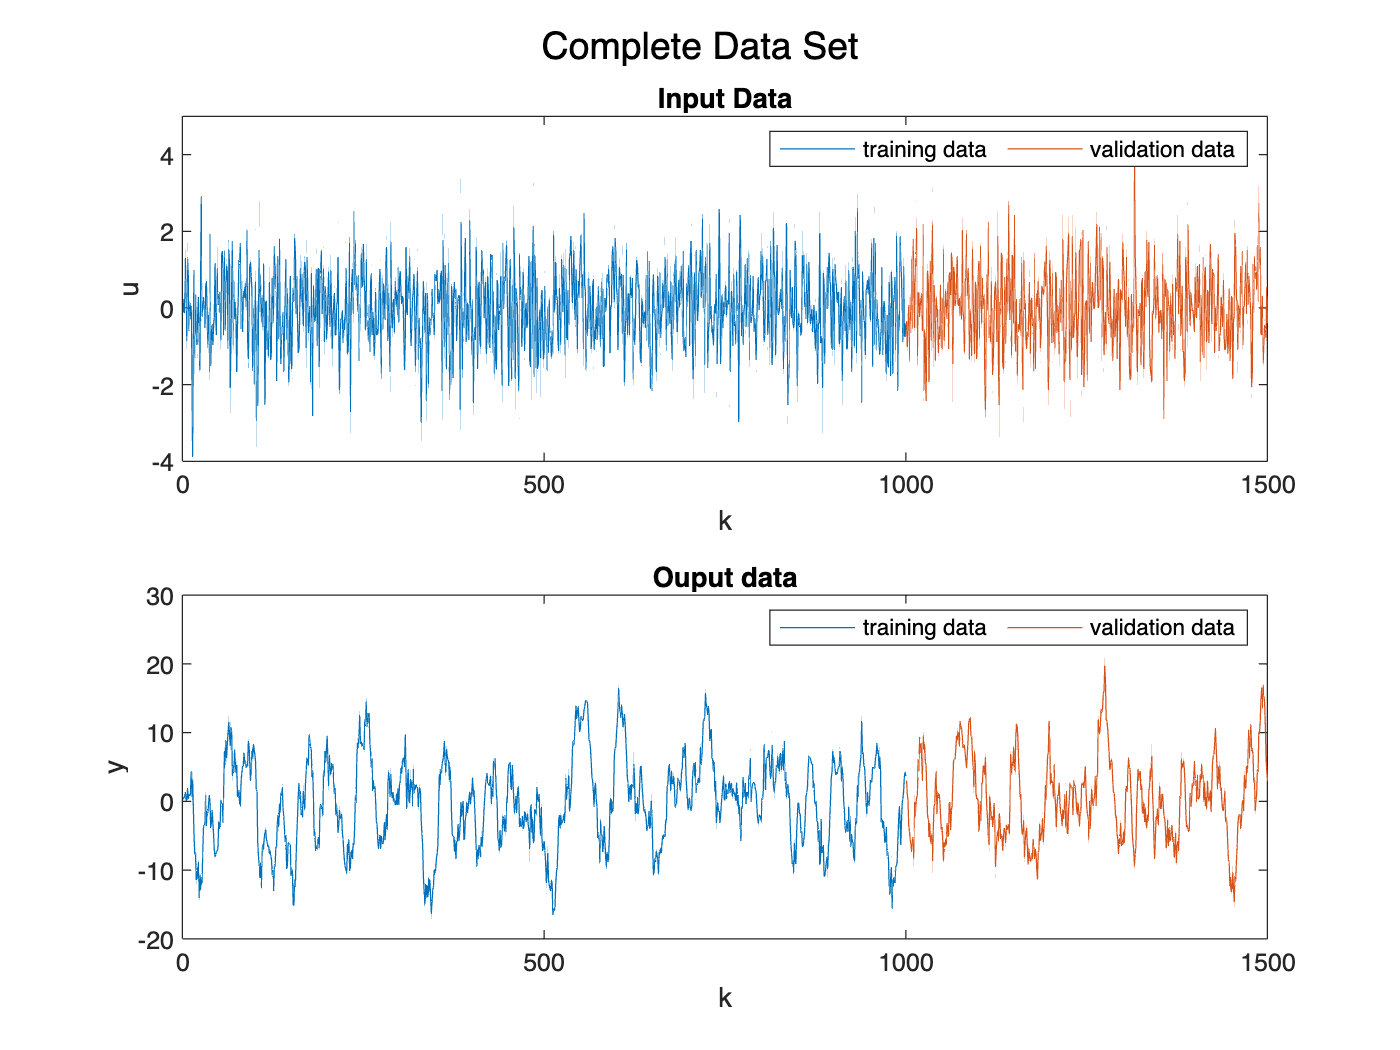

% DO NOT CHANGE THIS CODE
clear all
load iodata.mat
addpath('./function_folder')

end_train = floor(length(y)*2/3); %split in 2/3 - 1/3

%training data
y_train = y(1:end_train);
u_train = u(1:end_train);
%validation data
y_val = y(end_train+1:end);
u_val = u(end_train+1:end);

%plot data set
plot_toydataset(u_train,u_val,y_train,y_val)

### **a)**  Implementation of PO-MOESP

We first implement the PO-MOESP algorithm for the Output Error System and apply it to the training set (no validation step). To facilitate the implementation, we split it in several subproblems. The block size is selected as `s = 100.`

#### I. Hankel-Matrices

**Compute** the Hankel matrices `U_hankel` with $U_{\textrm{hankel}} =\left\lbrack \begin{array}{c}
U_p \\
U_f 
\end{array}\right\rbrack$and `Y_hankel`` with `$Y_{\textrm{hankel}} =\left\lbrack \begin{array}{c}
Y_p \\
Y_f 
\end{array}\right\rbrack$by adapting the code below. 

**Important**: Do **not** change the variables `(u_train,  y_train)` and variable names (`U_hankel` and `Y_hankel) `and the block size `s = 100`, otherwise the test-function will not work! 

% DO NOT CHANGE THIS CODE
s = 100;

Please write your implementation below: 

% YOUR CODE HERE

U_hankel = hankel(u_train(1:2*s),u_train(2*s:end_train)); %hankelmatrix of inputs
Y_hankel = hankel(y_train(1:2*s),y_train(2*s:end_train)); %hankelmatrix of outputs

Test-function for Hankel matrices.

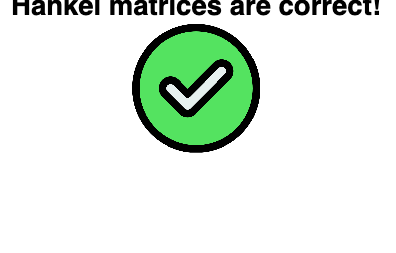

test_hankelmatrices(U_hankel, Y_hankel);

#### II. Compute L_32 from LQ factorization 

**Compute** the matrix` L_32 `with $\left\lbrack \begin{array}{c}
U_f \\
Z\\
Y_f 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
L_{11}  & 0 & 0\\
L_{21}  & L_{22}  & 0\\
L_{21}  & L_{32}  & L_{33} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
Q_1^T \\
Q_2^T \\
Q_3^T 
\end{array}\right\rbrack$, $Z=\left\lbrack \begin{array}{c}
U_p \\
Y_p 
\end{array}\right\rbrack$ by adapting the code below. 

**Important**: Do **not** change the variable name (L_32`)`, otherwise the test-function will not work! 

Please write your implementation below: 

% YOUR CODE HERE

L = qr([U_hankel(s+1:2*s,:);U_hankel(1:s,:);Y_hankel]',0)';
L_32 = L(3*s+1:4*s,s+1:3*s);

Test-function for L_32.

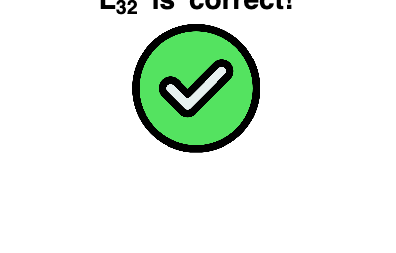

 test_L_32(L_32);

#### III.  Determine model order 

**Plot** the singular values of L_32 by adapting the code below. **Choose** a model order and **motivate **your choice**.** Also, make sure to **visualize** the graph in a meaningfull manner.

***Answer******: ***

- *I would choose a model order of 2, since there seem to be two dominant singular values when looking at the plot below. *

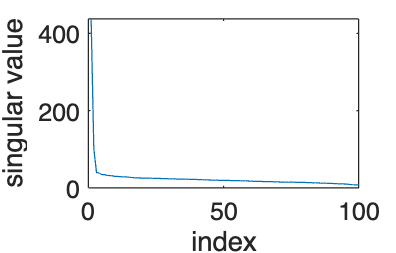

% YOUR CODE HERE

plot(svd(L_32))
ylabel('singular value')
xlabel('index')

Regardless of the previously determined model order, all test functions in part b) rely on a numerical comparison for the case `n = 3. `Therefore, the system order is fixed to `n = 3`.  

#### IV. Compute the system matrices A and C

**Compute** the system matrices `A` and `C` by adapting the code below. 

% DO NOT CHANGE THIS CODE
n = 3;

**Important**: The test functions works with a numeric comparison of variables. Please do **not** change the variable name (`A, C) `and the value `n = 3. O`therwise the test-function will not work! 

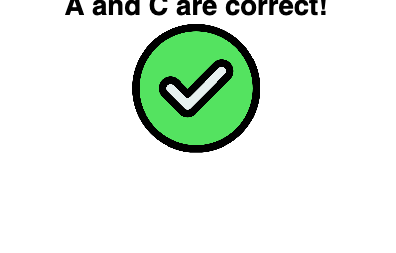

% YOUR CODE HERE

l = 1;
[U, S, V] = svd(L_32,"econ");

C = U(1:l,1:n);
A = U(1:(s-1)*l,1:n)\U(l+1:end,1:n);

test_A_C(A,C)

#### V. Compute x_0 and the system matrices B and D

**Compute** the `x_0 `and the system matrices `B` and `D` by adapting the code below.  

**Important**: The test functions works with a numeric comparison of variables. Please **stack** `x0` and the system matrices `B` and `D` **in the order **`x0, B, D`. Do **not** change the variable name (`x_0, B, D) `and the value `n = 3.` Please use the** backslash operator** `\ `to solve a linear system. O`t`herwise the test-function will not work! 

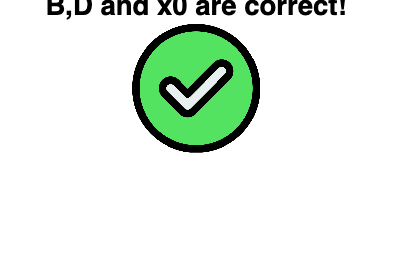

% YOUR CODE HERE
m = 1;
O = zeros(l*end_train,n);
P = zeros(l*end_train,n*m);

for k=1:end_train
    O(k,:) = C*A^(k-1);
    if k < end_train
        for j = 1:k
            P(k+1,:) = P(k+1,:)+C*A^(k-j)*u_train(j);
        end
    end
end

Phi = [O, P, u_train];
x0BD=Phi\y_train;
x0=x0BD(1:n);
B=x0BD(n+1:2*n);
D = x0BD(2*n+1);

test_B_D_x0(B,D,x0)

#### VI. PO-MOESP

**Combine** the segments above in the function `pomoesp``,` that computes the matrices `A_po_moesp,B_po_moesp,C_po_moesp,D_po_moesp `and the initial condition `x0_po_moesp, `given the inputs `u_train, `the measured outputs `y_train `and the block size `s. `You can use the file `pomoesp.m` provided and then copy the whole function to the bottom of the life-script or write it in the life-script directly.  

Make sure to **plot the singular values **within the function and to **provide the user with the option to input the system order based on the plot of the singular values**. The variable `n`** is not an input argument** of the pomoesp() function. For this exercise, please choose `n = 3 `**during runtime**`. `

**Important**: The test functions works with a numeric comparison of variables. Do **not** change the variable name` (A_toy,B_toy,C_toy,D_toy,x0_toy)` and give `n = 3` as an input during runtime`. O`therwise the test-function will not work! 

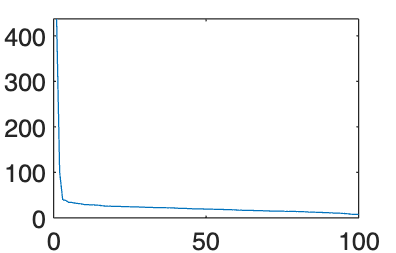

% Please delete the line aboves and uncomment the function call below when
% you have implemented the function pomoesp().
% DO NOT CHANGE THIS CODE

[A_toy,B_toy,C_toy,D_toy,x0_toy] = pomoesp(u_train,y_train,s); 

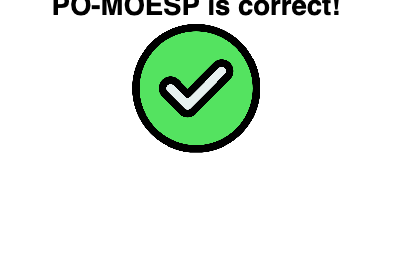

clf

test_pomoesp(A_toy,B_toy,C_toy,D_toy,x0_toy)

### b) Simulation, VAF and RMSE

Now we simulate the system and implement functions to compute the VAF and RMSE to assess the quality of the model.

#### I. Simulate the system

**Write** a **function** `simsystem` that simulates the state of the system `xhat_toy` and the system output `yhat_toy `given any input vector **u** and matrices `A_toy,B_toy,C_toy,D_toy` as well as initial condition `x0_toy. `The function should return the state vector `xhat_toy` and the estimated output vector `yhat_toy`. You can use the file `simsystem.m `provided and then copy the whole function to the bottom of the life-script or write it in the life-script directly. You are **not** allowed to use any Matlab built-in functions such as `ss(), lsim(), step(), `etc. 

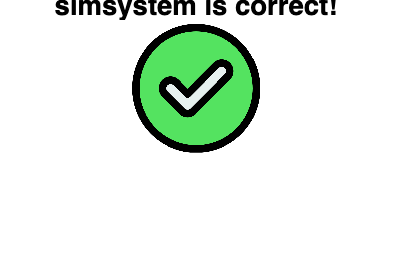

% DO NOT CHANGE THIS CODE
[yhat_toy,xhat_toy] = simsystem(A_toy,B_toy,C_toy,D_toy,x0_toy,u_train); 
test_simsystem;

#### II. Compute VAF 

**Write** a **function** `VAF, `that computes the Variance Acocunted For (VAF) given the measured and estimated outputs `y_train `and `yhat_toy, `respectively. You can use the file `VAF.m` provided and then copy the whole function to the bottom of the life-script or write it in the life-script directly. Please do not end the line with a semicolon here, such that the **output of the function is displayed** in the exported pdf.

% YOUR CODE HERE
vaf_toy = VAF(y_train,yhat_toy)

vaf_toy = 95.1852

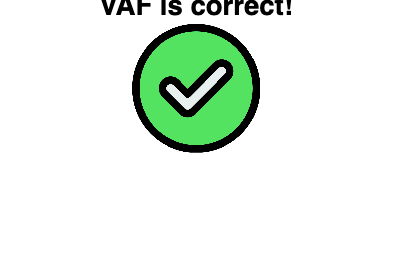

test_VAF();

#### III. Compute RMSE

**Write** a **function** `RMSE, `that computes the Root Mean Squared Error (RMSE) given the measured and estimated outputs `y_train `and `yhat_toy, `respectively. You can use the file `RMSE.m` provided and then copy the whole function to the bottom of the life-script or write it in the life-script directly. Please do not end the line with a semicolon here, such that the **output of the function is displayed** in the exported pdf.

% YOUR CODE HERE
rmse_toy = RMSE(y_train,yhat_toy) 

rmse_toy = 1.3750

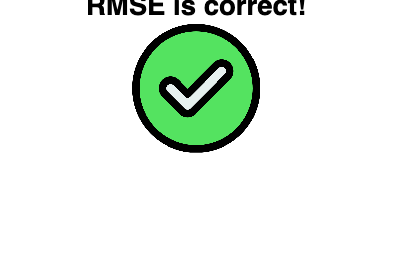

test_RMSE();

### c) Validation step

Now we perform the validation step to assess the quality of the model.

#### I. Simulate system with validation data

**Simulate** the system for the validation data. **Explain** what initial state and input sequence you use to simulate your system for the validation step.

***Answer******: ***

- *The complete data is used for simulation, using the previous initial condition. This way, the state will converge to a suitable 'initial condition' for the time interval used for validation.*

% YOUR CODE HERE
[yhat_toy_complete,xhat_toy_complete] = simsystem(A_toy,B_toy,C_toy,D_toy,x0_toy,u);  

#### II. Calculate VAF and RMSE for validation data

**Calculate **the VAF and RMSE for the validation step as `vaf_toy_validate` and `rmse_toy_validate`, respectively. **Explain** which part of the output sequence you need to use to compute the VAF and RMSE.

*Hint: If you get an error in the test-function, check both the output sequence selected for the VAF and RMSE and the combination of the initial state and the input sequence in the question above.*

**Important**: The test functions works with a numeric comparison of variables. Do **not** change the variable name` (vaf_toy_validate, rmse_toy_validate). ``O`therwise the test-function will not work! 

***Answer******: ***

- *The last third of the output sequence is used since the corresponding inputs belong to the validation set.*

vaf_toy_validate = VAF(y_val,yhat_toy_complete(end_train+1:end))

vaf_toy_validate = 93.5718

rmse_toy_validate = RMSE(y_val,yhat_toy_complete(end_train+1:end))

rmse_toy_validate = 1.4947

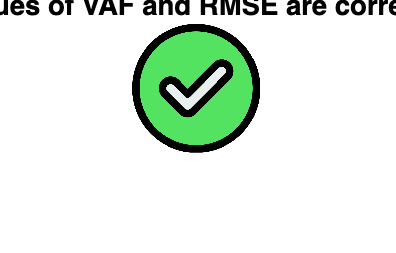

test_validation_VAF_RMSE(vaf_toy_validate, rmse_toy_validate);

#### III. Plot results

In the last step, we want to **plot** the validation data. For this, please **use** the function `plot_toydata_results(y,yhat,vaf,rmse), `where the** first argument** is the **true validation data**, the **second argument** is the **estimated validation data**, the t**hird argument **the **VAF of the validation data** and the **fourth argument** the **RMSE of the validation data**. Please **uncomment** the code below and give the correct input arguments for the function. A good way to visualize the results is to overlay the true data and the validation data. In an actual identification cycle, we would now go back and rerun the po-moesp algorithm with different parameters to see if we can improve the results until we are hapy with them. This is exactly what we are going to do in the next section.

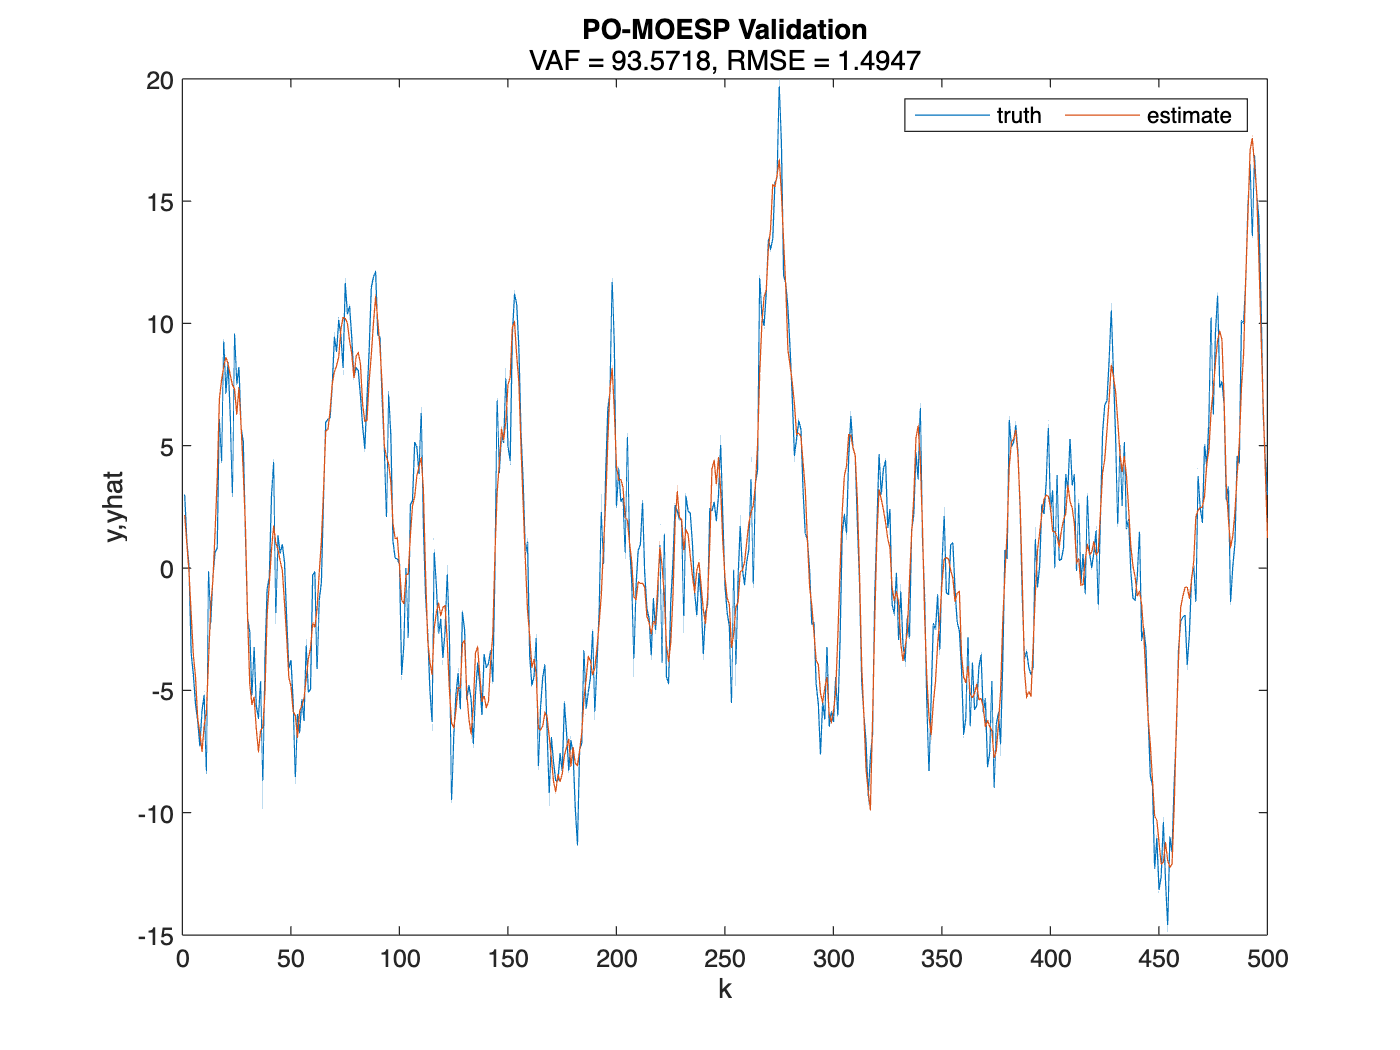

plot_toydata_results(y_val,yhat_toy_complete(end_train+1:end),vaf_toy_validate,rmse_toy_validate)

### d) Identification cycle with PO-MOESP

Now we consider the [Cascaded Tanks with Overflow](https://www.nonlinearbenchmark.org/benchmarks/cascaded-tanks) benchmark. The system has a hard saturation nonlinearity combined with weakly nonlinear behaviour. Nevertheless, we can get good results with a linear identification algorithm. The data set already provides us with an estimation data set `(uEst,yEst)` and an validation data set `(uVal,yVal). `Consequently, we don't need to to a Training-Validation split, but can directly start with the identification cyce.

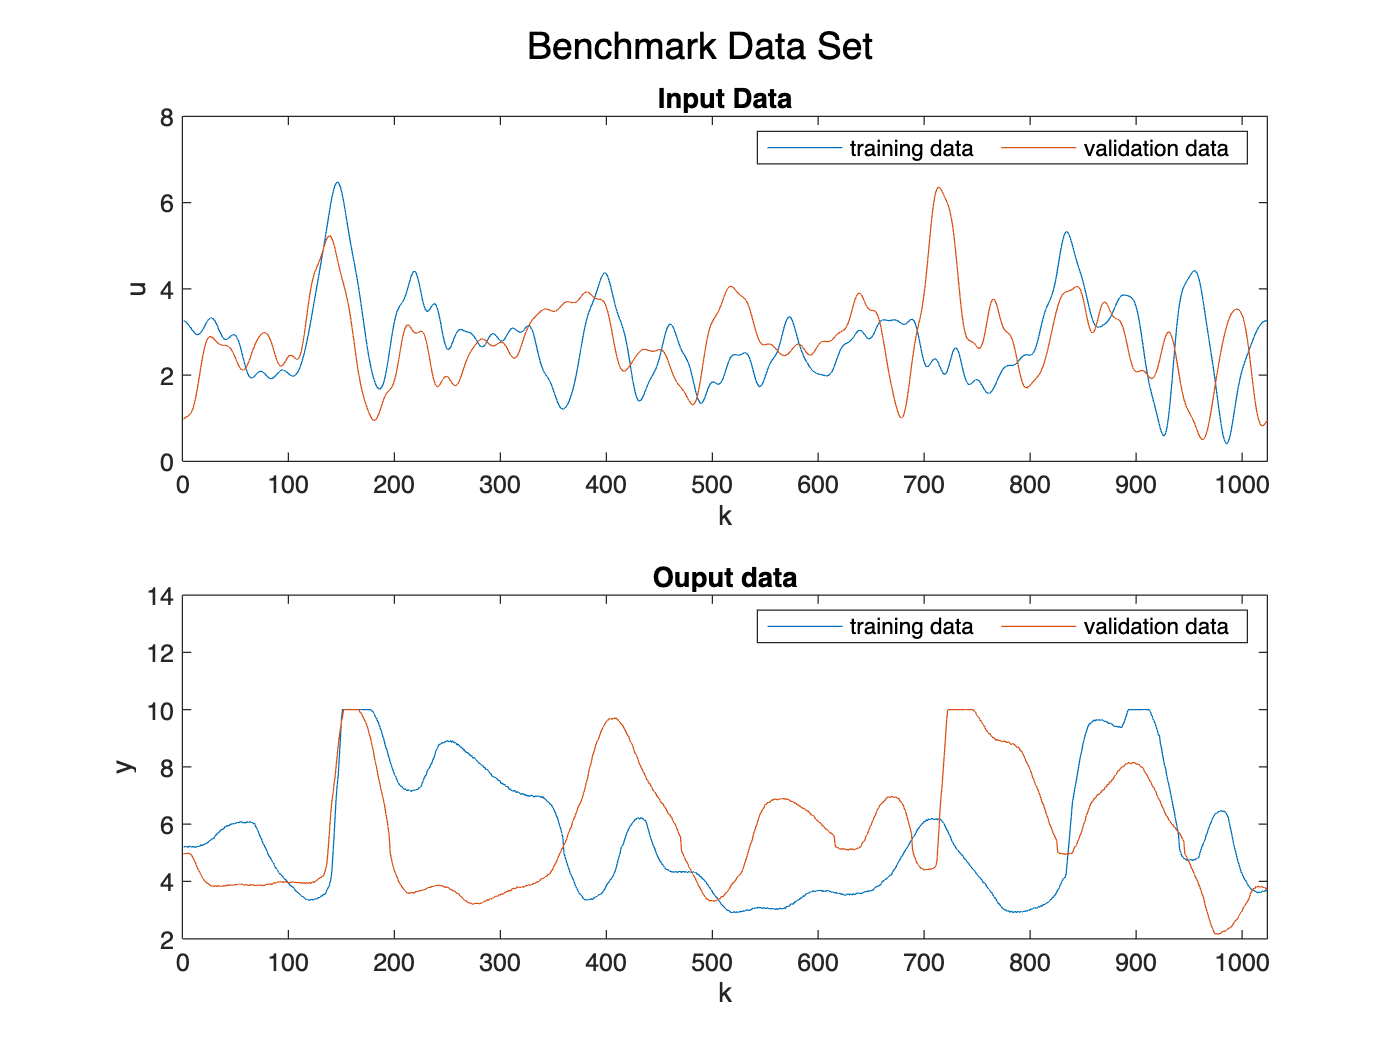

% DO NOT CHANGE THIS CODE
clear all
load dataBenchmark.mat
addpath('./function_folder')

%plot data set
plot_benchmark(uEst,uVal,yEst,yVal);

#### I. POMOESP for training data

**Apply** the PO-MOESP algorithm on the training data set. **Motivate**, which system order and block-size you chose. That can take multiple iterations of the identification cycle.  

***Answer******: ***

- *Please write your answer here*

% YOUR CODE HERE

s = 100;

N = length(uEst);
n = 3;

U_hankel = hankel(uEst(1:2*s),uEst(2*s:N));
Y_hankel = hankel(yEst(1:2*s),yEst(2*s:N));

L = qr([U_hankel(s+1:2*s,:);U_hankel(1:s,:);Y_hankel]',0)';
L_32 = L(3*s+1:4*s,s+1:3*s);

% plot(svd(L_32))

l = 1;
[U, ~, ~] = svd(L_32,"econ");

C = U(1:l,1:n);
A = U(1:(s-1)*l,1:n)\U(l+1:end,1:n);

m = 1;
O = zeros(l*N,n);
P = zeros(l*N,n*m);

for k=1:N
    O(k,:) = C*A^(k-1);
    if k < N
        for j = 1:k
            P(k+1,:) = P(k+1,:)+C*A^(k-j)*uEst(j);
        end
    end
end

Phi = [O, P, uEst];
x0BD=Phi\yEst;
x0=x0BD(1:n);
B=x0BD(n+1:2*n);
D = x0BD(2*n+1);

#### II. Simulation, VAF and RMSE for training data

**Simulate** the estimated system for the training data set. Then, **compute** the VAF and RMSE for the training data. **Plot** the true and the estimated values and include the VAF and RMSE in the title. Please do not end the line with a semicolon here, such that the **output of the function is displayed** in the exported pdf.

% YOUR CODE HERE
[yhat,xhat] = simsystem(A,B,C,D,x0,uEst);

vaf = VAF(yEst,yhat)

vaf = 97.3386


rmse = RMSE(yEst,yhat) 

rmse = 0.9769

#### III. Validation Step

**Test** the PO-MOESP model on the validation data and **compute** the VAF and RMSE for the validation data. **Plot** your results with the code provided below. **Plot** the true and the estimated values and include the VAF and RMSE in the title. Please do not end the line with a semicolon here, such that the **output of the function is displayed** in the exported pdf. **Explain** what initial state and input sequence you use to simulate the system for the validation step. 

***Answer******: ***

- *Please write your answer here*

% YOUR CODE HERE


### **e) Bonus Exercise**

#### **I. PO-MOESP vs PEM**

**Reflect** on the differences regarding the implementation of PEM and PO-MOESP: Which algorithm do you think is more versatile? What are the benefits and the drawbacks of PO-MOESP and PEM? How do the results of PEM and PO-MOESP differ?

***Answer******: ***

- *Please write your answer here*

### **II. Combination of PO-MOESP and PEM**

It is possible to combine the benefits of PO-MOESP and PEM by combining both algorithms. Use the system matrices A,B,C, D  you have computed with PO-MOESP for the benchmark data set as an initial guess for PEM. Please **answer** the following two questions: Do you see an improvement of the model on the validation data after the PEM iterations? How much improvement on the VAF and RMSE can you get compared to PO-MOESP from question d?

***Answer******: ***

- *Please write your answer here*

% YOUR CODE HERE

## Functions

### POMOESP()

function [A,B,C,D,x0]=pomoesp(u,y,s)
% Instructions:
% Implement your subspace ID method here.
% Use the following function inputs and outputs.

% Function INPUT 
% u         system input (matrix of size N x m)
% y         system output (matrix of size N x l)
% s         block size (scalar)
%
% Function OUTPUT
% A         System matrix A (matrix of size n x n)
% B         System matrix B (matrix of size n x m)
% C         System matrix C (matrix of size l x n)
% D         System matrix D (matrix of size l x m)
% x0        Initial state (vector of size n x one)

% YOUR CODE HERE   

N = length(u);
n = 3;

U_hankel = hankel(u(1:2*s),u(2*s:N));
Y_hankel = hankel(y(1:2*s),y(2*s:N));

L = qr([U_hankel(s+1:2*s,:);U_hankel(1:s,:);Y_hankel]',0)';
L_32 = L(3*s+1:4*s,s+1:3*s);

plot(svd(L_32))

l = 1;
[U, ~, ~] = svd(L_32,"econ");

C = U(1:l,1:n);
A = U(1:(s-1)*l,1:n)\U(l+1:end,1:n);

m = 1;
O = zeros(l*N,n);
P = zeros(l*N,n*m);

for k=1:N
    O(k,:) = C*A^(k-1);
    if k < N
        for j = 1:k
            P(k+1,:) = P(k+1,:)+C*A^(k-j)*u(j);
        end
    end
end

Phi = [O, P, u];
x0BD=Phi\y;
x0=x0BD(1:n);
B=x0BD(n+1:2*n);
D = x0BD(2*n+1);
end

### SIMSYSTEM()

function [y,x] = simsystem(A,B,C,D,x0,u)
% Instructions:
% Simulating a linear dynamic system given input u, matrices A,B,C,D ,and
% initial condition x(0)
%
%
% Function INPUT
% A system matrix (matrix of size n x n)
% B system matrix (matrix of size n x m)
% C system matrix (matrix of size l x n)
% D system matrix (matrix of size l x m)
% x0 initial state (matrix of size n x one)
% u system input (matrix of size N x m)
%
% Function OUTPUT
% x state of system (matrix of size N x n)
% y system output (matrix of size N x l)

% YOUR CODE HERE

[n, m] = size(B); 
[l, ~] = size(C); 
N = size(u, 1);   

x = zeros(N, n);
y = zeros(N, l);

x(1, :) = x0';

for k = 1:N
    y(k, :) = (C * x(k, :)' + D * u(k, :)')';
    if k < N
        x(k + 1, :) = (A * x(k, :)' + B * u(k, :)')';
    end
end
end

### VAF()

function vaf = VAF(y,yhat)
% Instructions:
% Implement the calculation of the VAF here.
%
% Function INPUT
% y    measured system output (matrix of size N x l)
% yhat simulated system output (matrix of size N x l)
%
% Function OUTPUT
% VAF Variance Accounted For (scalar)

% YOUR CODE HERE
   
N = length(y);
   
var_e = sum((y - yhat).^2)/N;

var_y =  sum(y.^2)/N;

vaf = 100*(1 - var_e/var_y);

end

### RMSE()

function rmse = RMSE(y,yhat)   
% Instructions:
% Implement the calculation of the RMSE here.
%
% Function INPUT
% y    measured system output (matrix of size N x l)
% yhat simulated system output (matrix of size N x l)
%
% Function OUTPUT
% RMSE Root Mean Squared Error (scalar)

% YOUR CODE HERE
    
N = length(y);

rmse = sqrt(sum((y - yhat).^2)/N);

end
